clc
clear, close all

%% Load the folder content in a struct

% Load the folder with all the .txt files
inputFolder1 = strcat(pwd, '\*.txt');
folder = dir(inputFolder1);

% Save user info
user = struct;

% For every txt file in the folder
for iuser = 1 : size(folder, 1)

    fileID = fopen(folder(iuser).name);
    % Load in a cell the content separated by the semicolon
    C = textscan(fileID, '%s','Delimiter',';');
    fclose(fileID);
    
    % Write in the struct the demographics
    user(iuser).id = folder(iuser).name;
    demographics = split(C{1,1}{1,1}, ' ');
    user(iuser).sex = string(demographics(1,1));
    user(iuser).age = str2double(demographics(2,1));

    % For every rating report the answers divided in songs, mappings and
    % rating
    for idx = 2 : size(C{1,1}, 1)
        tempAnswer = split(C{1,1}{idx, 1}, ' ');
        user(iuser).songs(idx - 1, 1) = string(tempAnswer(1,1));
        user(iuser).mappings(idx - 1, 1) = string(tempAnswer(2, 1));
        user(iuser).rates(idx - 1, 1) = str2double(tempAnswer(3,1));
    end
end

%% Prepare data


% Collect in 4 variables the different ratings per mapping
pitchTracking = zeros(size(user(1).mappings, 1)/4 * size(folder, 1), 1);
pitchTrackingOctaved = zeros(size(user(1).mappings, 1)/4 * ...
    size(folder, 1), 1);
audioHaptics = zeros(size(user(1).mappings, 1)/4 * size(folder, 1), 1);
noHaptics = zeros(size(user(1).mappings, 1)/4 * size(folder, 1), 1);
indexesMappings = ones(1, 4); % Store the indexes to write in the correct
                              % place of each mapping array.

% For every user
for idx = 1 : size(user, 2)
    % For every rating
    for ii = 1 : size(user(idx).rates, 1)
        switch user(idx).mappings(ii, 1) 
            case "pitchHaptics"
                pitchTracking(indexesMappings(1, 1), 1) = ...
                    user(idx).rates(ii, 1);
                indexesMappings(1, 1) = indexesMappings(1, 1) + 1;
            case "pitchHapticsOctaved"
                pitchTrackingOctaved(indexesMappings(1, 2), 1) = ...
                    user(idx).rates(ii, 1);
                indexesMappings(1, 2) = indexesMappings(1, 2) + 1;
            case "normalHaptics"
                audioHaptics(indexesMappings(1, 3), 1) = ...
                    user(idx).rates(ii, 1);
                indexesMappings(1, 3) = indexesMappings(1, 3) + 1;
            case "noHaptics"
                noHaptics(indexesMappings(1, 4), 1) = ...
                    user(idx).rates(ii, 1);
                indexesMappings(1, 4) = indexesMappings(1, 4) + 1;
        end
    end
end


% For every song find the different ratings per mapping and overall ratings
indexesSongs = ones(1, 3);  % Store the indexes to write in the correct 
                            % place of each mapping array.
duo.all = [];
duo.pH = [];
duo.phO = [];
duo.aH = [];
duo.noH = [];
band = duo;
orchestra = duo;

% For every user
for idx = 1 : size(user, 2)
    % For every song
    for ii = 1 : size(user(idx).rates, 1)
        switch user(idx).songs(ii, 1) 
            case "Duo.wav"
                indexesSongs(1, 1) = indexesSongs(1, 1) + 1;
                duo = cat(1, duo, map(ii, user(idx)));
                
            case "Band.wav"
                indexesSongs(1, 2) = indexesSongs(1, 2) + 1;
                band = cat(1, band, map(ii, user(idx)));
                
            case "Orchestra.wav"
                indexesSongs(1, 3) = indexesSongs(1, 3) + 1;
                orchestra = cat(1, orchestra, map(ii, user(idx)));
        end
    end
end


% Demographics 
avgAge = mean(vertcat(user.age));
males = 0;
females = 0;

for idx = 1 : size(user, 2)
    if user(idx).sex == "Male"
        males = males + 1;
    else 
        females = females + 1;
    end
end

% Prepare matrices with different mappings per each song
duoMappings = [vertcat(duo.aH), vertcat(duo.pH), vertcat(duo.phO), ...
    vertcat(duo.noH)];
bandMappings = [vertcat(band.aH), vertcat(band.pH), vertcat(band.phO), ...
    vertcat(band.noH)];
orchestraMappings = [vertcat(orchestra.aH), vertcat(orchestra.pH),...
    vertcat(orchestra.phO), vertcat(orchestra.noH)];


% Same mapping for each type of song
audioHapticSeparated = [vertcat(duo.aH), vertcat(band.aH),...
    vertcat(orchestra.aH)];
pitchTrackingSeparated = [vertcat(duo.pH), vertcat(band.pH),...
    vertcat(orchestra.pH)];
pitchTrackingOctavedSeparated = [vertcat(duo.phO), vertcat(band.phO),...
    vertcat(orchestra.phO)];
noHapticsSeparated = [vertcat(duo.noH), vertcat(band.noH),...
    vertcat(orchestra.noH)];


%% Graphs
% Labels
songsLabels = {'Duo', 'Band', 'Orchestra'};
mappingsLabels = {'Audio Haptics', 'Pitch Tracking', ...
    'Pitch Tracking Octaved', 'No Haptics'};

% Ratings for every mapping with all songs
figure
tiledlayout(1, 2)

nexttile
boxplot([audioHaptics, pitchTracking, pitchTrackingOctaved, noHaptics],...
    'Labels', mappingsLabels);

title('Overall ratings for mapping')
ylabel('Rating compared to reference')

% Ratings for every song with all mappings
nexttile
boxplot([vertcat(duo.all), vertcat(band.all), vertcat(orchestra.all)], ...
    'Labels', songsLabels);

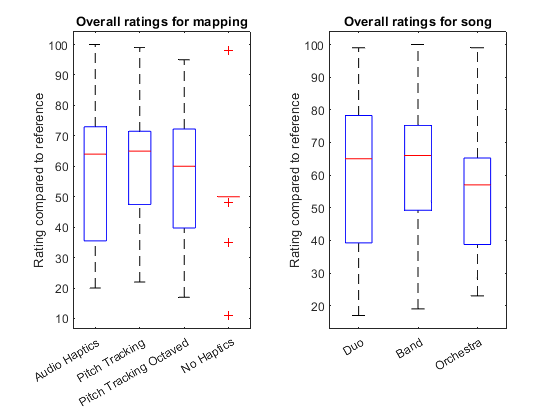

title('Overall ratings for song')
ylabel('Rating compared to reference')

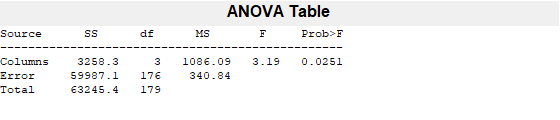


anova1([audioHaptics, pitchTracking, pitchTrackingOctaved, noHaptics], mappingsLabels);

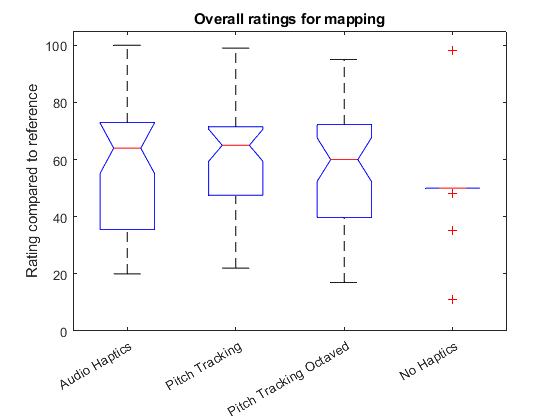

ylim([0 105])
title('Overall ratings for mapping')
ylabel('Rating compared to reference')

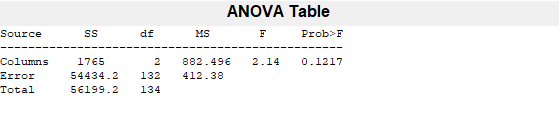


anova1([vertcat(duo.all), vertcat(band.all), vertcat(orchestra.all)], songsLabels);

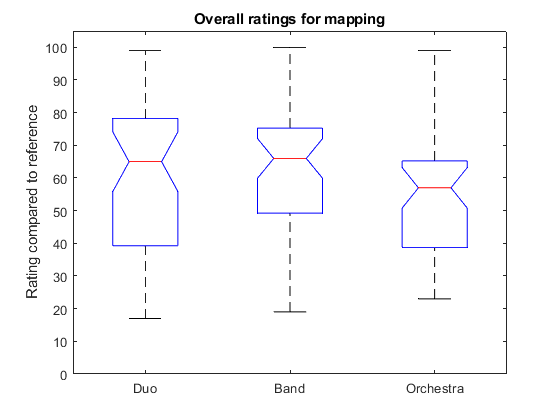

ylim([0 105])
title('Overall ratings for mapping')
ylabel('Rating compared to reference')

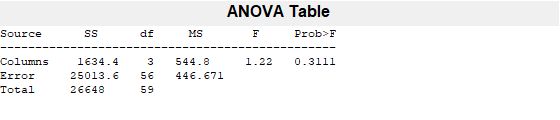



% Ratings for every song divided by mappings
[pDuo, tblDuo, statsDuo] = anova1(duoMappings, mappingsLabels);

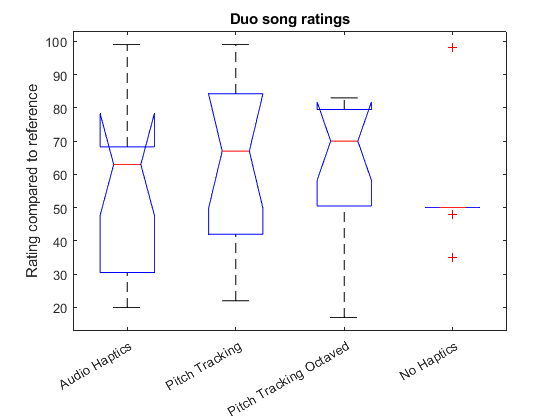

title('Duo song ratings')
ylabel('Rating compared to reference')

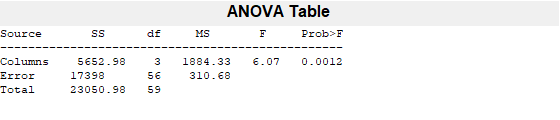


[pBand, tblBand, statsBand] = anova1(bandMappings, mappingsLabels);

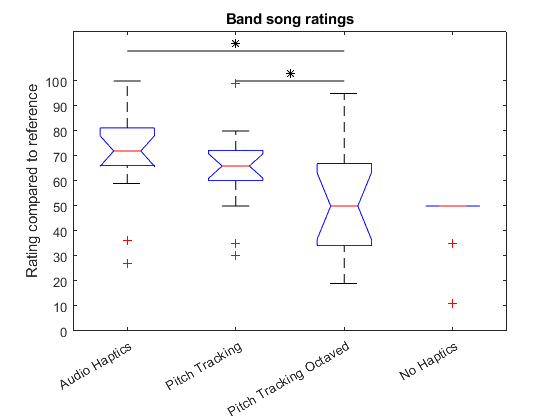

% ylim([0 100])
yt = get(gca, 'YTick');
axis([xlim    0  ceil(max(yt)*1.2)])
yticks([0 : 10 : 100])
xt = get(gca, 'XTick');
hold on
plot(xt([1 3]), [1 1]*max(yt)*1.12, '-k',  mean(xt([1 3])), max(yt)*1.15, '*k')
% plot(xt([1 2]), [1 1]*max(yt)*1.04, '-k',  mean(xt([1 2])), max(yt)*1.07, '*k')
plot(xt([2 3]), [1 1]*max(yt)*1., '-k',  mean(xt([2 3])), max(yt)*1.03, '*k')
hold off
title('Band song ratings')
ylabel('Rating compared to reference')

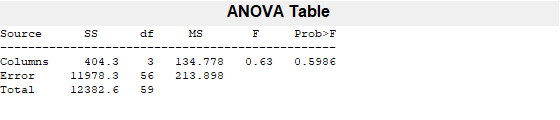


[pOrchestra, tblOrchestra, statsOrchestra] = ...
    anova1(orchestraMappings, mappingsLabels);

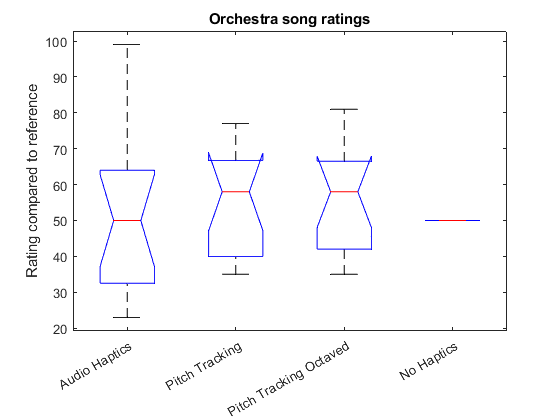

title('Orchestra song ratings')
ylabel('Rating compared to reference')

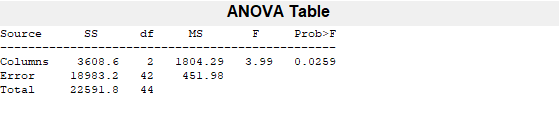


% Ratings of each mapping divided by song
[pSepAH, tblSepAH, statsSepAH] = anova1(audioHapticSeparated, songsLabels);yt = get(gca, 'YTick');

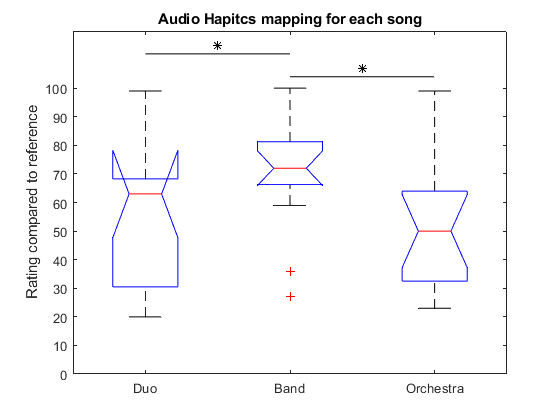

axis([xlim    0  ceil(max(yt)*1.2)])
yticks([0 : 10 : 100])
xt = get(gca, 'XTick');
hold on
plot(xt([1 2]), [1 1]*max(yt)*1.12, '-k',  mean(xt([1 2])), max(yt)*1.15, '*k')
plot(xt([2 3]), [1 1]*max(yt)*1.04, '-k',  mean(xt([2 3])), max(yt)*1.07, '*k')

hold off
title('Audio Hapitcs mapping for each song')
ylabel('Rating compared to reference')

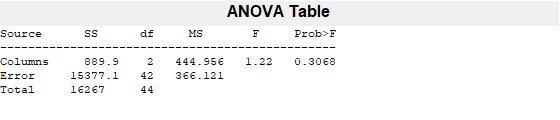


[pSepPH, tblSepPH, statsSepPH] = anova1(pitchTrackingSeparated, songsLabels);

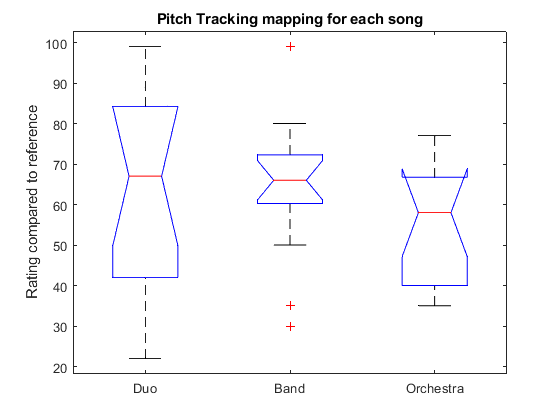

title('Pitch Tracking mapping for each song')
ylabel('Rating compared to reference')

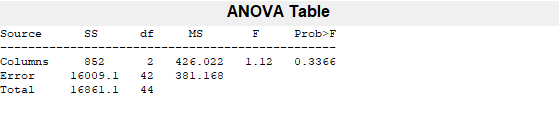


[pSepPHO, tblSepPHO, statsSepPHO] = anova1(pitchTrackingOctavedSeparated,...
    songsLabels);

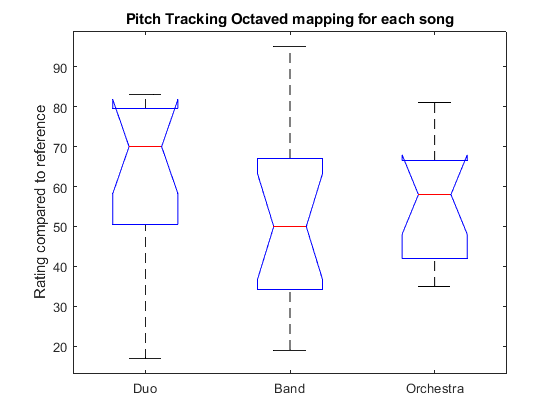

title('Pitch Tracking Octaved mapping for each song')
ylabel('Rating compared to reference')

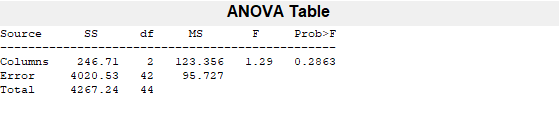


[pSepNoH, tblSepNoH, statsSepNoH] = anova1(noHapticsSeparated, songsLabels);

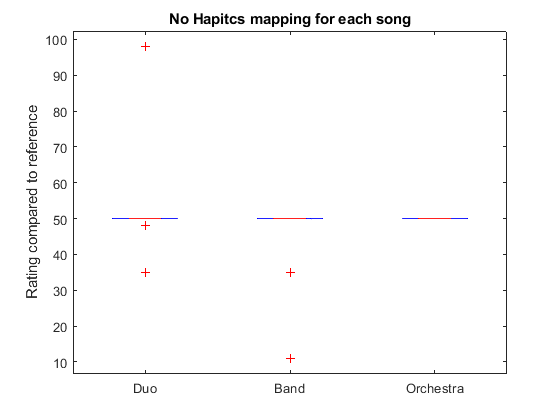

title('No Hapitcs mapping for each song')
ylabel('Rating compared to reference')


%% Functions


function out = map(songIndex, in)
% For every rating
switch in.mappings(songIndex, 1)
    case "pitchHaptics"
        out.all = in.rates(songIndex);
        out.pH = in.rates(songIndex);
        out.phO = [];
        out.aH = [];
        out.noH = [];
    case "pitchHapticsOctaved"
        out.all = in.rates(songIndex);
        out.pH = [];
        out.phO = in.rates(songIndex);
        out.aH = [];
        out.noH = [];
    case "normalHaptics"
        out.all = in.rates(songIndex);
        out.pH = [];
        out.phO = [];
        out.aH = in.rates(songIndex);
        out.noH = [];
    case "noHaptics"
        out.all = []; % in.rates(songIndex); Does it make sense to keep it?
        out.pH = [];
        out.phO = [];
        out.aH = [];
        out.noH = in.rates(songIndex);
end
end